# Continues decoding

1. Deal with temperal lag

In most experiments, the linear filter incorporates multiple temporal lags between behavioral and neural data, reflecting the fact that neural activity can influence movement at several different time points. However, using many lags greatly increases the number of model parameters. To simplify, we can use only a single lag by appropriately shifting the behavioral data in time. Commonly, the kinematic data is shifted by 140 ms (two bins in this context), which provides a reasonable estimate of the typical delay from M1 neural activity to hand movement.

clear all; clc;
load continuous1.mat
lag = 2;
train.kin_shift = kin(lag+1:end,:);
train.rate_shift = rate(1:end-lag,:);

2. Compute linear filter coefficients

Y = X*A ---> Y = hand position, X = firing rate, A = coefficient matrix

train.Y = train.kin_shift;
train.X = [train.rate_shift, ones(size(train.rate_shift,1), 1)];
train.A = pinv(train.X) * train.Y;

train.prediction = train.X * train.A;
train.MSE = mean(sum((train.kin_shift - train.prediction).^2, 2));

3. Assess the performance of the coefficients obtained from the training dataset

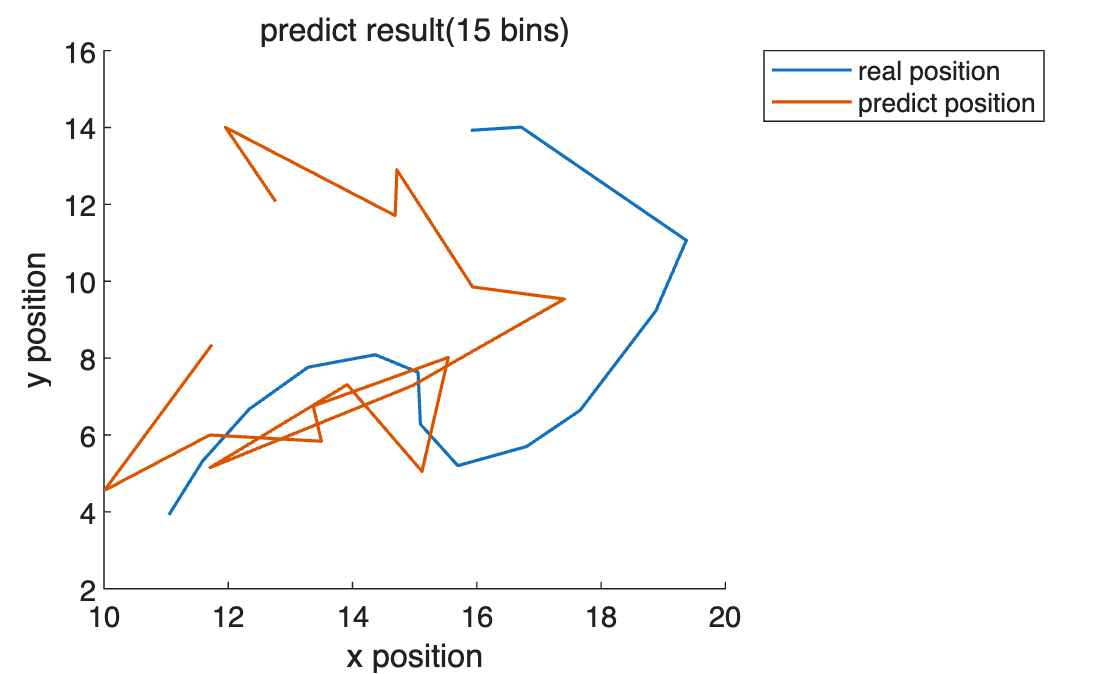

% plot a track for 1 sec
figure;
hold on;
plot(train.Y(130:145,1),train.Y(130:145,2), 'LineWidth', 1.2, 'DisplayName', 'real position');
plot(train.prediction(130:145,1),train.prediction(130:145,2), 'LineWidth', 1.2, 'DisplayName', 'predict position');
xlabel('x position');
ylabel('y position');
title('predict result(15 bins)');
legend('Location','northeastoutside');
hold off;

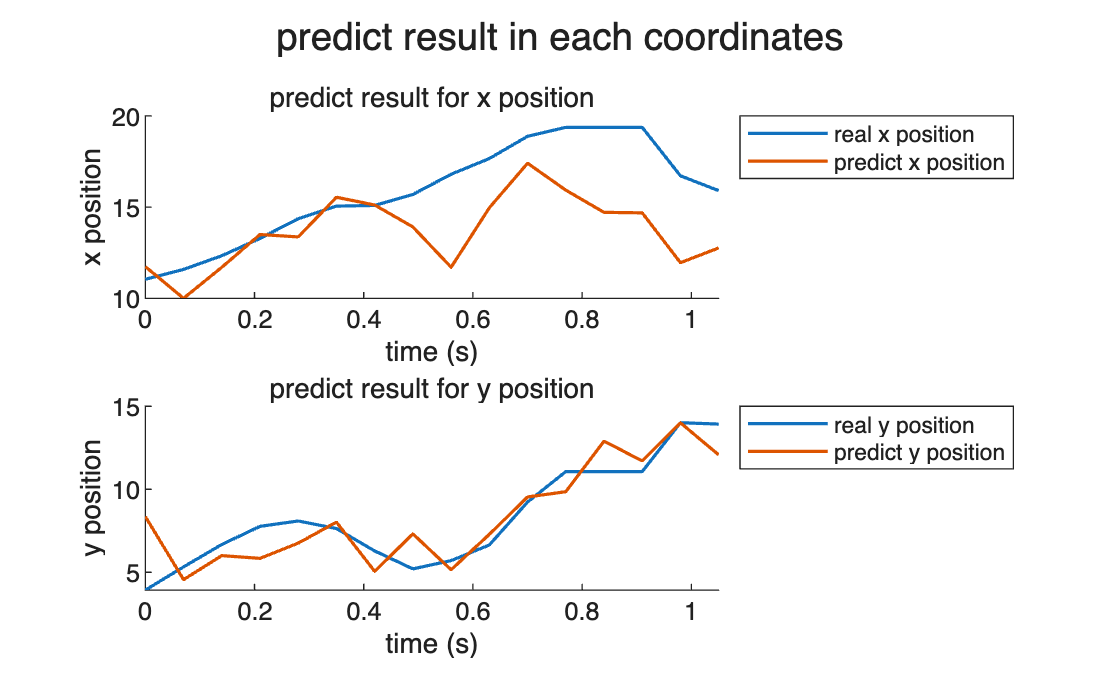

% predict results for each coordinate within a 1 sec window
train.idx_start = 130;
train.idx_end = 145;
train.time_vec = ((0:(train.idx_end-train.idx_start)) * 70) / 1000;
figure;
subplot(2,1,1);
hold on;
plot(train.time_vec, train.kin_shift(train.idx_start:train.idx_end,1), 'DisplayName', 'real x position', 'LineWidth', 1.2);
plot(train.time_vec, train.prediction(train.idx_start:train.idx_end,1), 'DisplayName', 'predict x position', 'LineWidth', 1.2);
xlim([0, 1.05]);
xlabel('time (s)');
ylabel('x position');
title('predict result for x position');
legend('Location','northeastoutside');
hold off;
subplot(2,1,2);
hold on;
plot(train.time_vec, train.kin_shift(train.idx_start:train.idx_end,2), "DisplayName", 'real y position', 'LineWidth', 1.2);
plot(train.time_vec, train.prediction(train.idx_start:train.idx_end,2), 'DisplayName', 'predict y position', 'LineWidth', 1.2);
xlim([0, 1.05]);
xlabel('time (s)');
ylabel('y position');
title('predict result for y position');
legend('Location','northeastoutside');
hold off;
sgtitle('predict result in each coordinates');

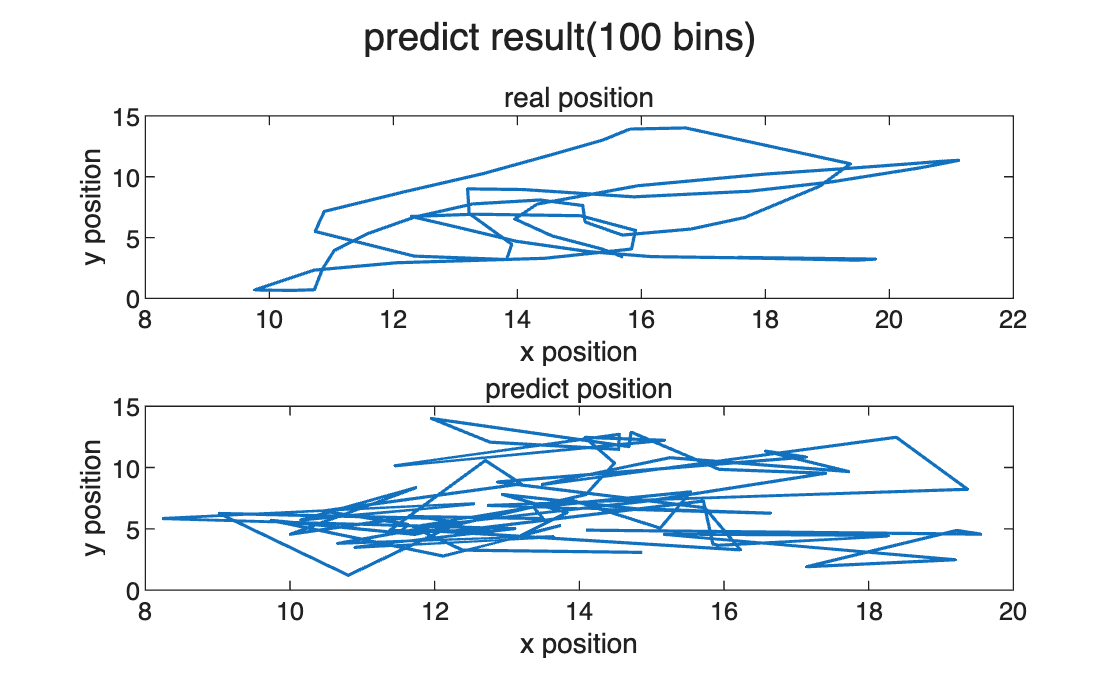

% plot track for 5 sec
figure;
subplot(2,1,1)
plot(train.Y(100:175,1),train.Y(100:175,2), 'LineWidth', 1.2);
xlabel('x position');
ylabel('y position');
title('real position');
subplot(2,1,2)
plot(train.prediction(100:175,1),train.prediction(100:175,2), 'LineWidth', 1.2);
xlabel('x position');
ylabel('y position');
title('predict position');
sgtitle('predict result(100 bins)');

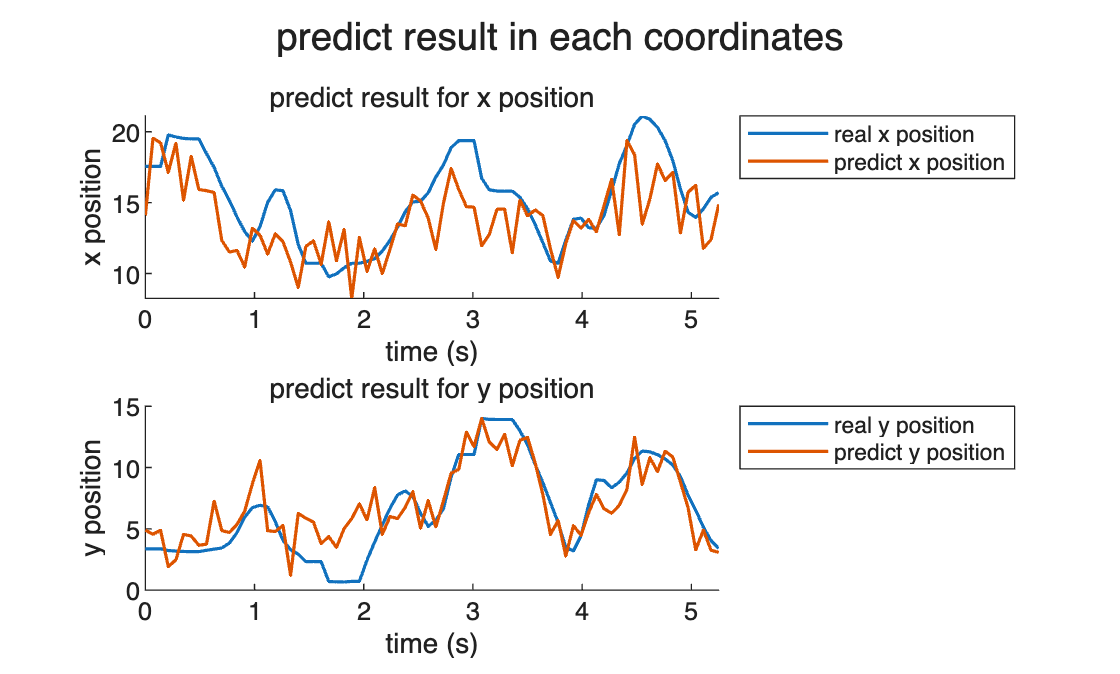

% predict results for each coordinate within a 5 sec window
train.idx_start = 100;
train.idx_end = 175;
train.time_vec = ((0:(train.idx_end-train.idx_start)) * 70) / 1000;
figure;
subplot(2,1,1);
hold on;
plot(train.time_vec, train.kin_shift(train.idx_start:train.idx_end,1), 'DisplayName', 'real x position', 'LineWidth', 1.2);
plot(train.time_vec, train.prediction(train.idx_start:train.idx_end,1), 'DisplayName', 'predict x position', 'LineWidth', 1.2);
xlim([0, 5.25]);
xlabel('time (s)');
ylabel('x position');
title('predict result for x position');
legend('Location','northeastoutside');
hold off;

subplot(2,1,2);
hold on;
plot(train.time_vec, train.kin_shift(train.idx_start:train.idx_end,2), 'DisplayName', 'real y position', 'LineWidth', 1.2);
plot(train.time_vec, train.prediction(train.idx_start:train.idx_end,2), 'DisplayName', 'predict y position', 'LineWidth', 1.2);
xlim([0, 5.25]);
xlabel('time (s)');
ylabel('y position');
title('predict result for y position');
legend('Location','northeastoutside');
hold off;
sgtitle('predict result in each coordinates');

4.  Evaluate the performance of the coefficients on the test dataset.

We need to use a new dataset as the test set to evaluate whether the coefficient matrix learned from the training data performs well on unseen data. This helps us determine if the model can generalize to new situations, rather than just fitting the training data.

load continuous2.mat
test.kin_shift = kin(lag+1:end,:);
test.rate_shift = rate(1:end-lag,:);
test.Y = test.kin_shift;
test.X = [test.rate_shift, ones(size(test.rate_shift,1), 1)];

test.prediction = test.X * train.A;
test.MSE = mean(sum((test.kin_shift - test.prediction).^2, 2));

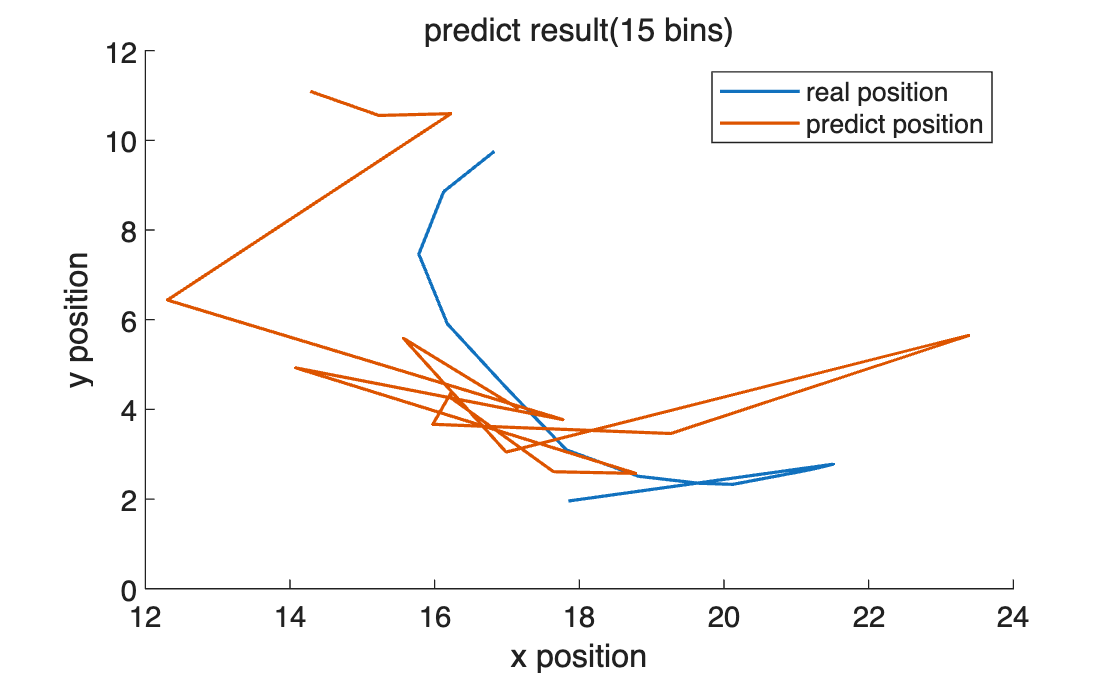

% plot a track for 1 sec
figure;
hold on;
plot(test.Y(130:145,1),test.Y(130:145,2), 'LineWidth', 1.2, 'DisplayName', 'real position');
plot(test.prediction(130:145,1),test.prediction(130:145,2), 'LineWidth', 1.2, 'DisplayName', 'predict position');
xlabel('x position');
ylabel('y position');
title('predict result(15 bins)');
legend();
hold off;

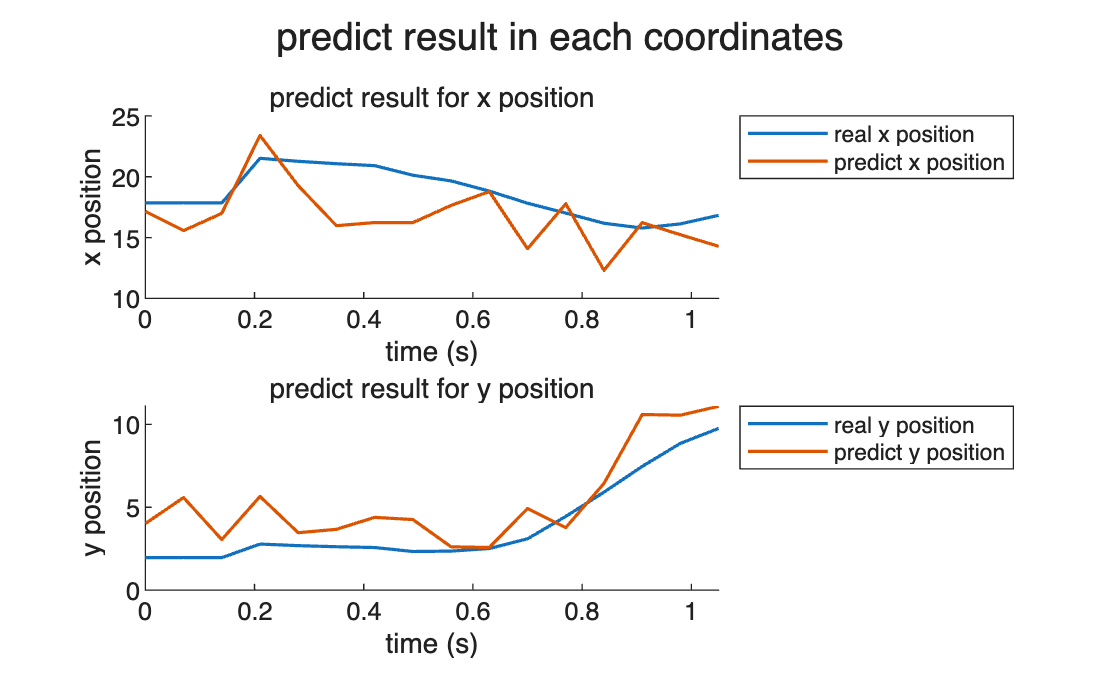

% predict results for each coordinate within a 1 sec window
test.idx_start = 130;
test.idx_end = 145;
test.time_vec = ((0:(test.idx_end-test.idx_start)) * 70) / 1000;
figure;
subplot(2,1,1);
hold on;
plot(test.time_vec, test.kin_shift(test.idx_start:test.idx_end,1), 'DisplayName', 'real x position', 'LineWidth', 1.2);
plot(test.time_vec, test.prediction(test.idx_start:test.idx_end,1), 'DisplayName', 'predict x position', 'LineWidth', 1.2);
xlim([0, 1.05]);
xlabel('time (s)');
ylabel('x position');
title('predict result for x position');
legend('Location','northeastoutside');
hold off;
subplot(2,1,2);
hold on;
plot(test.time_vec, test.kin_shift(test.idx_start:test.idx_end,2), "DisplayName", 'real y position', 'LineWidth', 1.2);
plot(test.time_vec, test.prediction(test.idx_start:test.idx_end,2), 'DisplayName', 'predict y position', 'LineWidth', 1.2);
xlim([0, 1.05]);
xlabel('time (s)');
ylabel('y position');
title('predict result for y position');
legend('Location','northeastoutside');
hold off;
sgtitle('predict result in each coordinates');

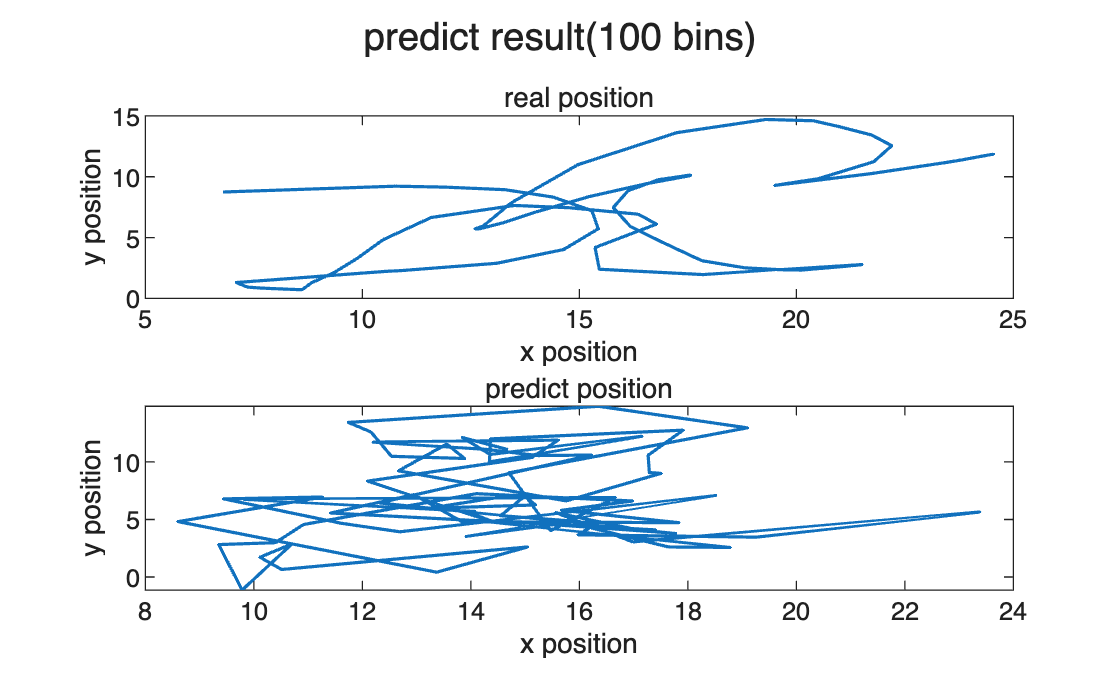


% plot in a bigger range
figure;
subplot(2,1,1)
plot(test.Y(100:175,1),test.Y(100:175,2), 'LineWidth', 1.2);
xlabel('x position');
ylabel('y position');
title('real position');
subplot(2,1,2)
plot(test.prediction(100:175,1),test.prediction(100:175,2), 'LineWidth', 1.2);
xlabel('x position');
ylabel('y position');
title('predict position');
sgtitle('predict result(100 bins)');

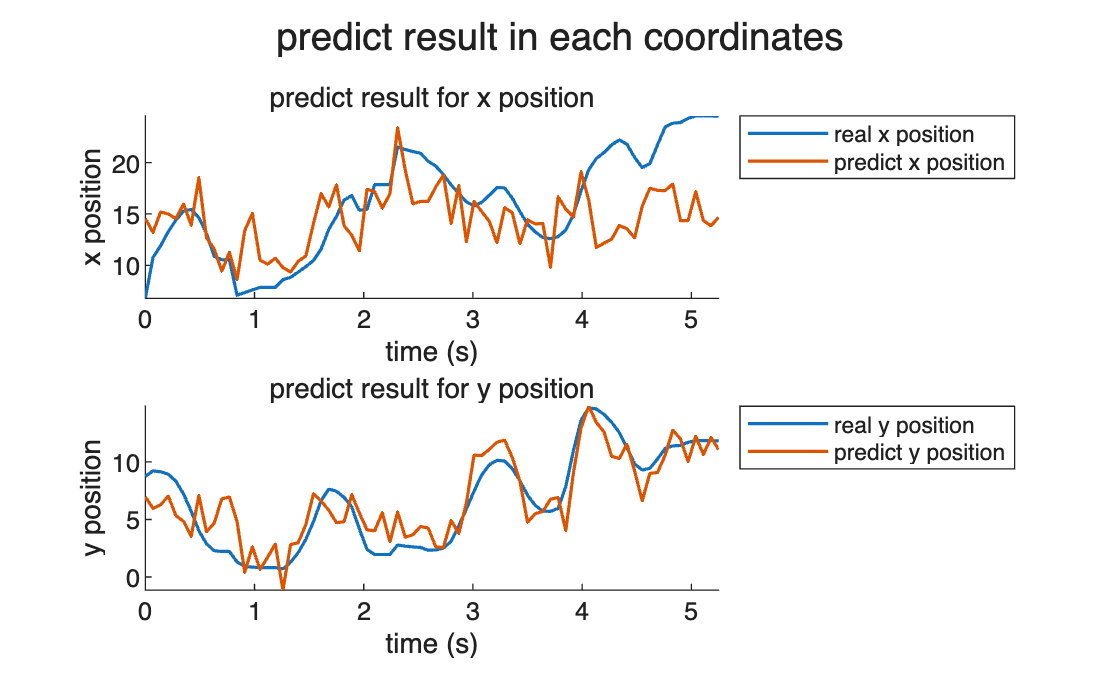

% predict results for each coordinate within a 5 sec window
test.idx_start = 100;
test.idx_end = 175;
test.time_vec = ((0:(test.idx_end-test.idx_start)) * 70) / 1000;
figure;
subplot(2,1,1);
hold on;
plot(test.time_vec, test.kin_shift(test.idx_start:test.idx_end,1), 'DisplayName', 'real x position', 'LineWidth', 1.2);
plot(test.time_vec, test.prediction(test.idx_start:test.idx_end,1), 'DisplayName', 'predict x position', 'LineWidth', 1.2);
xlim([0, 5.25]);
xlabel('time (s)');
ylabel('x position');
title('predict result for x position');
legend('Location','northeastoutside');
hold off;

subplot(2,1,2);
hold on;
plot(test.time_vec, test.kin_shift(test.idx_start:test.idx_end,2), 'DisplayName', 'real y position', 'LineWidth', 1.2);
plot(test.time_vec, test.prediction(test.idx_start:test.idx_end,2), 'DisplayName', 'predict y position', 'LineWidth', 1.2);
xlim([0, 5.25]);
xlabel('time (s)');
ylabel('y position');
title('predict result for y position');
legend('Location','northeastoutside');
hold off;
sgtitle('predict result in each coordinates');